# Decoding context

In the file `DecodingDataRead.m`, we first took the binarized calcium activity and took the sum of events in 2 s bins (60 frames). We then restricted analysis to: 

(1) times when the mouse was running, and 

(2) when the mouse was in context "1" or "2," representing two different cue configurations in the maze. 

Finally, only activity from place cells were used. The resulting pre-processed data was saved for each mouse in a subfolder under the name `binned_activity_decode.mat`.

rootdir = "";
folders = ["M119"+filesep "M120"+filesep "M292"+filesep "M319"+filesep ...
    "M231"+filesep "M314"+filesep "M316"+filesep "M318"+filesep "M210"+filesep];
cohort = ["D1","D1","D1","D1","G1","G1","G1","G1","D1"];
sessions = ["early", "trained", "grouping"];

## Estimate SVM performance for each animal & each condition.

ablate_percent=1;
ablation = 'None';

test_accuracy = nan(length(folders),3);
validation_accuracy = nan(length(folders),3);
s_max = length(sessions);

weights = cell(length(folders),3);
corrs = cell(length(folders),3);

num_cells = zeros(length(folders),3);

for f = 1:length(folders)
    for s = 1:s_max
       try
            A=load(folders(f)+"binned_activity_decode_"+sessions(s)+"_runrest_all_cells.mat");
            
            ds = 20; % how many samples to downsample

            N_cells = size(A.a_use,2);
            N_cells_use = round(ablate_percent*N_cells);
            idx_cells_use = [];
            if strcmp(ablation,'random')
                % shuffle the cells
                subset_cells = randperm(N_cells);
                idx_cells_use = subset_cells(1:N_cells_use);
                corrs{f,s} = A.corr_coef(idx_cells_use);

            elseif strcmp(ablation, 'ascend')
                % sort the cells by increasing corr coef (most remap are
                % first)
                [corr_temp,idx_cells_use] = topkrows(A.corr_coef,N_cells_use,'ascend');
                corrs{f,s} = corr_temp;
            
            elseif strcmp(ablation,'descend')
                [corr_temp,idx_cells_use] = topkrows(A.corr_coef,N_cells_use,'descend');
                corrs{f,s} = corr_temp;
            elseif strcmp(ablation,'None')
                idx_cells_use = 1:N_cells_use;
                corrs{f,s} = A.corr_coef(idx_cells_use);
            end

            a_use_sub = A.a_use(1:ds:end,idx_cells_use);            
            context_use_sub = A.context_use(1:ds:end);

            num_cells(f,s) = length(idx_cells_use);

            % % reshuffle context
            % shuffle_context_ind = randperm(size(context_use_sub,1));
            % context_use_sub = context_use_sub(shuffle_context_ind);
            
            hpartition = cvpartition(context_use_sub,'Holdout',0.25,'Stratify',true);
            
            X_train = a_use_sub(training(hpartition),:);
            Y_trian = context_use_sub(training(hpartition));
            
            classificationSVM = fitcsvm(...
                X_train, ...
                Y_trian, ...
                'KernelFunction', 'rbf', ...
                'PolynomialOrder', [], ...
                'KernelScale', 'auto', ...
                'BoxConstraint', 1, ... % usuaally 1
                'Standardize', true);
                %'ScoreTransform','sign');
            
            % k-fold partitioning validation
            partitionedModel = crossval(classificationSVM, 'KFold', 20);
            [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
            validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
            
            validation_accuracy(f,s) = validationAccuracy;

            % test set on hold out
            X_test = a_use_sub(test(hpartition),:);
            Y_test = context_use_sub(test(hpartition));
            
            [testPredictions,testScores] = predict(classificationSVM,X_test);
            
            testAccuracy = 1 - loss(classificationSVM,X_test,Y_test);
            
            rocObj_test = rocmetrics(Y_test, testScores,[1,2]);   

            test_accuracy(f,s) = testAccuracy;

            % comparing SVM weights to remapping metric
            weights{f,s} = classificationSVM.Beta;

            display("Completed "+ folders(f)+"binned_activity_decode_"+sessions(s)+".mat")

       catch e
            display("Skipping "+ folders(f)+"binned_activity_decode_"+sessions(s)+".mat")
       end
    end
end

    "Skipping M119\binned_activity_decode_early.mat"



    "Completed M119\binned_activity_decode_trained.mat"

    "Completed M119\binned_activity_decode_grouping.mat"



    "Skipping M120\binned_activity_decode_early.mat"



    "Completed M120\binned_activity_decode_trained.mat"

    "Completed M120\binned_activity_decode_grouping.mat"



    "Skipping M292\binned_activity_decode_early.mat"



    "Completed M292\binned_activity_decode_trained.mat"

    "Completed M292\binned_activity_decode_grouping.mat"



    "Skipping M319\binned_activity_decode_early.mat"



    "Completed M319\binned_activity_decode_trained.mat"

    "Completed M319\binned_activity_decode_grouping.mat"



    "Skipping M231\binned_activity_decode_early.mat"



    "Completed M231\binned_activity_decode_trained.mat"

    "Completed M231\binned_activity_decode_grouping.mat"



    "Skipping M314\binned_activity_decode_early.mat"



    "Completed M314\binned_activity_decode_trained.mat"

    "Completed M314\binned_activity_decode_grouping.mat"



    "Skipping M316\binned_activity_decode_early.mat"



    "Completed M316\binned_activity_decode_trained.mat"

    "Completed M316\binned_activity_decode_grouping.mat"



    "Skipping M318\binned_activity_decode_early.mat"



    "Completed M318\binned_activity_decode_trained.mat"

    "Completed M318\binned_activity_decode_grouping.mat"



    "Skipping M210\binned_activity_decode_early.mat"



    "Completed M210\binned_activity_decode_trained.mat"



    "Skipping M210\binned_activity_decode_grouping.mat"



### Stats for Panel B

clear;
datat = readtable("decoder_results_deltas_repeat_runrest.xlsx");
WithinSubjectData = table(categorical({'PC','NonPC','PC','NonPC'})',categorical({'D','D','G','G'})',VariableNames=["CellSets","Tasks"]);
rm = fitrm(datat,'Score1-Score4 ~ 1','WithinDesign',WithinSubjectData);
ranova(rm,'WithinModel','CellSets+Tasks'028

ans = 6×8 table
                              SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    __________    ______    __________    __________    __________    __________

    (Intercept)                20.625    1         20.625    1817.5    1.0195e-09    1.0195e-09    1.0195e-09    1.0195e-09
    Error                    0.079435    7       0.011348                                                                  
    (Intercept):CellSets     0.026283    1       0.026283    3.8858      0.089327      0.089327      0.089327      0.089327
    Error(CellSets)     

rm.multcompare('Tasks','by','CellSets')

ans = 4×8 table
    CellSets    Tasks_1    Tasks_2    Difference     StdErr      pValue       Lower        Upper   
    ________    _______    _______    __________    ________    ________    _________    __________

     NonPC         D          G        0.013382     0.010627     0.24833    -0.011748      0.038511
     NonPC         G          D       -0.013382     0.010627     0.24833    -0.038511      0.011748
     PC            D          G        0.036288     0.011654    0.016991    0.0087306      0.063846
     PC            G          D       -0.036288     0.011654    0.016991    -0.063846    -0.0087306


rm.multcompare('CellSets','by','Tasks')

ans = 4×8 table
    Tasks    CellSets_1    CellSets_2    Difference     StdErr      pValue       Lower         Upper  
    _____    __________    __________    __________    ________    ________    __________    _________

      D        NonPC         PC          -0.068771     0.030997    0.062005      -0.14207    0.0045262
      D        PC            NonPC        0.068771     0.030997    0.062005    -0.0045262      0.14207
      G        NonPC         PC          -0.045864     0.028423     0.15064      -0.11307     0.021345
      G        PC            NonPC        0.045864     0.028423     0.15064     -0.021345      0.11307


boxplot(table2array(datat(:,[3,6,4,7,5,8])))

Error using  ()  (line 132)
Variable index exceeds table dimensions.

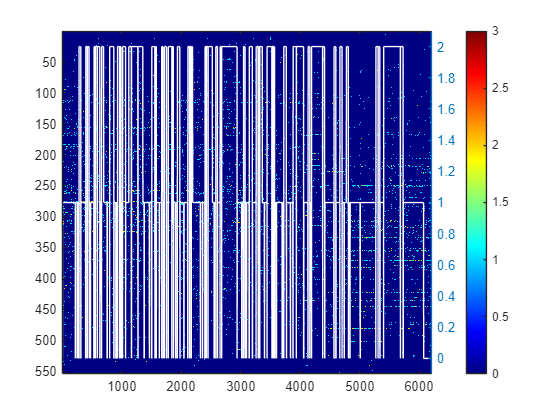

load 'M314\binned_activity_decode_trained_runrest_allcells_allframes.mat'

[context_use_long,sort_i_long] = sort(context_use);
A_move_max = movmax(a_use(sort_i_long,:),[1000,1000],1);

disc_i = nansum(A_move_max(context_use_long == 1,:),1)-nansum(A_move_max(context_use_long == 2,:),1);%./nansum(a_use,1);%(nansum(a_use(context_use == 1,:),1)-nansum(a_use(context_use == 2,:),1))./nansum(a_use,1);
disc_i = disc_i./nansum(A_move_max,1);

disc_i(isnan(disc_i)) = 0;
[~,sort_i] = sort(disc_i);

figure()
imagesc((1:size(a_use,1))/20,1:size(a_use,2),a_use(:,sort_i)')
colormap('jet')
colorbar()
%clim([0,2])
yyaxis right
plot((1:size(a_use,1))/20,context_use,'w')
ylim([-0.1,2.1])

%xlim([614,642])

